% Plot Exploration:
addpath(genpath('../Helpers'));
%% Set default datetime display properties (this doesn't affect the values stored, only their display/preview in MATLAB)
datetime.setDefaultFormats('default','yyyy-MM-dd hh:mm:ss.SSS');
time_reference = datenum('1970', 'yyyy');
output_found_videos_file_name = 'FoundVideoFiles.mat';
actigraphy_output_parent_path_root = 'E:\ActigraphyResults\BB';

curr_bbID = '02';
curr_actigraphy_folder = [actigraphy_output_parent_path_root, curr_bbID];
if ~exist(curr_actigraphy_folder,'dir')
    error(curr_actigraphy_folder); 
end

output_merged_actigraphy_timetables_file_name = ['MergedBoxActigraphyData_BB', curr_bbID, '_Timetables.mat'];

%         final_merged_actigraphy_filePath = fullfile(curr_actigraphy_folder, output_merged_actigraphy_timetables_file_name);
final_merged_actigraphy_filePath = output_merged_actigraphy_timetables_file_name;
if exist(final_merged_actigraphy_filePath, 'file')
    disp(['Loading ', final_merged_actigraphy_filePath, '...'])
    load(final_merged_actigraphy_filePath);
    disp('done.')
else
    error(['ERROR: ' final_merged_actigraphy_filePath ' does not exist!']);
end

ERROR: MergedBoxActigraphyData_BB02_Timetables.mat does not exist!

plot(curr_activity_timetable_hourly_binned.Time, counts_per_bin)

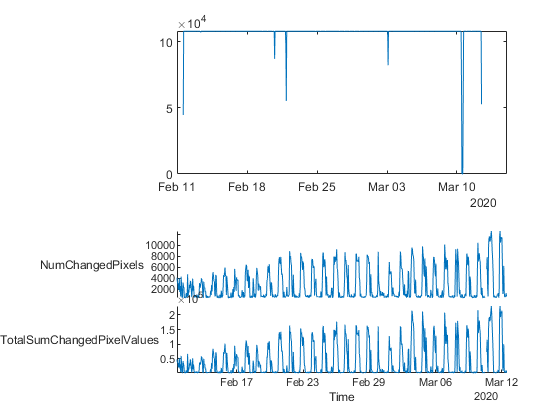

subplot(2,1,1)
plot(curr_activity_timetable_hourly_binned.Time, counts_per_bin)
subplot(2,1,2)
stackedplot(curr_activity_timetable_hourly_binned);

% curr_data = all_videos_output_data{3};
% curr_videos_data = curr_data.videoFilesData;
% curr_videos_data

activeOriginalVideosPathRoot = 'F:\Videos\BB';
curr_bbID = '06';
curr_folder = [activeOriginalVideosPathRoot, curr_bbID];
curr_search_string = fullfile(curr_folder, '*.mkv')

curr_search_string = 'F:\Videos\BB06\*.mkv'


curr_box_output_data.curr_bbID = curr_bbID;
curr_box_output_data.curr_folder = curr_folder;
curr_box_output_data.videoFilesData = FnFindVideoFiles(curr_folder,'.mkv');
curr_box_output_data.videoFilesData

ans = 156×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum



num_video_files = length(curr_box_output_data.videoFilesData);
% [status,values] = fileattrib(curr_search_string)

% [~,str] = dos('dir /T:C *.m');
% rgx = '(\d{4}\.\d{2}\.\d{2}\.\s+\d{2}:\d{2})\s+\d+\s+([^\n]+)';
% tkn = regexp(str,rgx,'tokens');
% tkn{:}

relevant_entires = curr_box_output_data.videoFilesData(1:20)

relevant_entires = 20×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum




for i = 1:length(relevant_entires)
    [~, relevant_entires(i).originalBaseName, relevant_entires(i).fileExtension] = fileparts(relevant_entires(i).name);
    curr_file_path = fullfile(relevant_entires(i).folder, relevant_entires(i).name);
    TimeStruct = GetFileTime(curr_file_path, 'UTC');
    relevant_entires(i).creation_time = TimeStruct.Creation;
    relevant_entires(i).modification_time = TimeStruct.Write;

    %t = datetime(Y,M,D,H,MI,S)
    temp.t = datetime(relevant_entires(i).creation_time);
    
    [OBSVideoBasename] = MakePhoOBSVideoBaseFileName(curr_bbID, temp.t);
    relevant_entires(i).expected_basename = OBSVideoBasename;

    %output_TimeStructs{end+1} = TimeStruct;
end
relevant_entires

relevant_entires = 20×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum
    originalBaseName
    fileExtension
    creation_time
    modification_time
    expected_basename


% 




## Merge FoundVideoFiles.mat results


foundVideoFilesName_Left = 'FoundVideoFiles-5-7-2020.mat';
foundVideoFilesName_Right = 'FoundVideoFiles_WatsonBB16.mat';
% foundVideoFilesName_Right = 'FoundVideoFiles_WatsonBB16-5-7-2020.mat';
foundVideoFilesName_MergedPath = 'FoundVideoFiles_Merged.mat';


% Loads all_videos_output_data
LoadedS = load(foundVideoFilesName_Left, 'activeTranscodedVideosPathRoot', 'bbIDs', 'all_videos_output_data', 'totalCombinedVideoCount', 'totalBoxFolderCount');
fprintf('Loaded %s: contains %i total videos spanning %i folders.\n', foundVideoFilesName_Left, LoadedS.totalCombinedVideoCount, LoadedS.totalBoxFolderCount);

Loaded FoundVideoFiles-5-7-2020.mat: contains 1536 total videos spanning 8 folders.


LoadedS_Right = load(foundVideoFilesName_Right, 'activeTranscodedVideosPathRoot', 'bbIDs', 'all_videos_output_data', 'totalCombinedVideoCount', 'totalBoxFolderCount');
fprintf('Loaded %s: contains %i total videos spanning %i folders.\n', foundVideoFilesName_Right, LoadedS_Right.totalCombinedVideoCount, LoadedS_Right.totalBoxFolderCount);

Loaded FoundVideoFiles_WatsonBB16.mat: contains 1536 total videos spanning 8 folders.



% Test for any new bbIDs to include:
[LeftOnly_BBIDs, commonBBIDs, RightOnly_BBIDs, phoDiffOutput] = fnDiffCellArrays(LoadedS.bbIDs, LoadedS_Right.bbIDs);

bbIDs = LoadedS.bbIDs;
all_videos_output_data = LoadedS.all_videos_output_data;
% totalCombinedVideoCount = LoadedS_Left.totalCombinedVideoCount;

% Add the new bbIDs unique to the right to the left
for i=1:length(RightOnly_BBIDs)
    curr_bbID = RightOnly_BBIDs{i};
    curr_rightIndex = phoDiffOutput.listB_Only_OriginalIndicies(i);

    all_videos_output_data{end+1} = LoadedS_Right.all_videos_output_data{curr_rightIndex};
    bbIDs{end+1} = LoadedS_Right.bbIDs{curr_rightIndex};
end




% Merge bbIDs with new BBIDs and get the unique ones:
% bbIDs = unique([LoadedS_Left.bbIDs, LoadedS_Right.bbIDs]);

		% Collected the videoFilesData for both the loaded and new files:
		fprintf('Merging results...\n');

Merging results...


		numNewVideos = 0;
		numExtantLoadedVideos = 0;

		numNewBBIDs = 0;


		%% Loop through the bbIDs:
		for i=1:length(bbIDs)
			curr_bbID = bbIDs{i};
			curr_folder = [activeTranscodedVideosPathRoot, curr_bbID];
			
			% The new results will have all of the old files (hopefully), the only thing we're interested in transfering is the pre-compueted information (like actigraphy processing state) from the loaded files.
			curr_box_output_data = all_videos_output_data{i};
			
			% Need to find corresponding index in loaded data for this bbID:
			found_corresponding_loaded_all_videos_index = false;
			corresponding_loaded_all_videos_index = -1;
			for loadedIndex = 1:length(LoadedS_Right.bbIDs)
				if strcmp(curr_bbID, LoadedS_Right.bbIDs{loadedIndex})
					corresponding_loaded_all_videos_index = loadedIndex;
					found_corresponding_loaded_all_videos_index = true;
				end
			end

			%% TODO: would greatly enhance efficiency if I made a temporary list of names and indicies from the loaded data and removed them as they were found. Currently n! performance I believe, but there are so few video files it probably doesn't matter.
			if found_corresponding_loaded_all_videos_index
				% If there is a correspodning bbID in the loaded data:
				loaded_box_output_data = LoadedS_Right.all_videos_output_data{corresponding_loaded_all_videos_index};
				% Loop through the recently found video files and figure out if anything needs to be updated
				for fileIndex = 1:length(curr_box_output_data.videoFilesData)
					was_video_file_found = false;
					for loadedFileIndex = 1:length(loaded_box_output_data.videoFilesData)
						if strcmpi(curr_box_output_data.videoFilesData(fileIndex).name, loaded_box_output_data.videoFilesData(loadedFileIndex).name)
							% Found matching entry in the loaded data.
							% Set the current actigraphy status and file output path from the loaded file:
                                                        if ~all_videos_output_data{i}.is_actigraphy_processed(fileIndex)
                                                            % IF actigraphy isn't processed in the loaded file, but is in the right file, set the loaded file status to that of the right file (which still might be False, indicating not processed)
                                                            all_videos_output_data{i}.is_actigraphy_processed(fileIndex) = loaded_box_output_data.is_actigraphy_processed(loadedFileIndex);
                                                        end
							if strcmpi(all_videos_output_data{i}.actigraphy_file_output_path{fileIndex},'')
                                                            % IF actigraphy path is empty in the loaded file, but is in the right file, set the loaded file status to that of the right file (which still might be False, indicating not processed)
                                                            all_videos_output_data{i}.actigraphy_file_output_path{fileIndex} = loaded_box_output_data.actigraphy_file_output_path{loadedFileIndex}; 
                                                        end
							
							%% TODO: are there any other computed fields that need to be loaded, like the parsed video time, etc?
							was_video_file_found = true;
							break;
						end
					end % end inner loaded file loop:
					
					if was_video_file_found
						numExtantLoadedVideos = numExtantLoadedVideos + 1;
					else
						numNewVideos = numNewVideos + 1;
					end

				end % end for curr_box_output_data.videoFilesData

			else
				numNewBBIDs = numNewBBIDs + 1;
				numNewVideos = numNewVideos + length(curr_box_output_data.videoFilesData);
			end % end if found_corresponding_loaded_all_videos_index

		end % end for
		fprintf('Merging Complete.\n'); % TODO: display total merged counts

Merging Complete.


		fprintf('    Found %i new videos spanning %i new folders.\n', numNewVideos, numNewBBIDs);

    Found 0 new videos spanning 0 new folders.



        perform_output_file_save = true;
	if perform_output_file_save
		% Save the result to a .mat file:
		save(foundVideoFilesName_MergedPath, 'activeTranscodedVideosPathRoot', 'bbIDs', 'all_videos_output_data', 'totalCombinedVideoCount', 'totalBoxFolderCount', '-v7.3');
		fprintf('    Result saved to %s\n', foundVideoFilesName_MergedPath);
	end

    Result saved to FoundVideoFiles_Merged.mat



% for i=1:length(bbIDs)
%     LoadedS_Left.all_videos_output_data{i}.is_actigraphy_processed(1)
%     LoadedS_Right.all_videos_output_data{i}.is_actigraphy_processed(1)
% end

ans = 1

ans = 0

ans = 1

ans = 0

ans = 1

ans = 0

ans = 1

ans = 0

ans = 1

ans = 0

ans = 0

ans = 0

ans = 1

ans = 1

ans = 0

ans = 0

## Retroactively Set up Quadrentizing/Muxing variables in FoundVideoFiles.mat files

% addpath(genpath("Helpers"))
% output_found_video_fileRef.output_found_videos_file_parent_path = 'Data\';
% output_found_video_fileRef.output_found_videos_file_name = 'FoundVideoFiles.mat'; % For Overseer:
% % output_found_videos_file_name = 'FoundVideoFiles_WatsonBB16.mat'; % For WatsonBB16:
% output_found_video_fileRef.fullpath = fullfile(output_found_video_fileRef.output_found_videos_file_parent_path, output_found_video_fileRef.output_found_videos_file_name);
% if ~exist(output_found_video_fileRef.fullpath, 'file')
%     fprintf('Error, file does not exist at %s!!! \n', output_found_video_fileRef.fullpath)
%     
% else
%     %% Load Existing 'FoundVideoFiles.mat' results:
%     LoadedS = load(output_found_video_fileRef.fullpath, 'activeTranscodedVideosPathRoot', 'bbIDs', 'all_videos_output_data', 'totalCombinedVideoCount', 'totalBoxFolderCount');
%     activeTranscodedVideosPathRoot = LoadedS.activeTranscodedVideosPathRoot;
%     bbIDs = LoadedS.bbIDs;
%     all_videos_output_data = LoadedS.all_videos_output_data;
%     totalCombinedVideoCount = LoadedS.totalCombinedVideoCount;
%     totalBoxFolderCount = LoadedS.totalBoxFolderCount;
%     
%     fprintf('Loaded %s: contains %i total videos spanning %i folders.\n', output_found_video_fileRef.fullpath, totalCombinedVideoCount, totalBoxFolderCount);
%     for i=1:length(bbIDs)
%         curr_num_video_files = length(all_videos_output_data{i}.videoFilesData)
%         
% %         LoadedS.all_videos_output_data{i}.is_quadrentized = zeros([curr_num_video_files, 1]);
% %         LoadedS.all_videos_output_data{i}.quadrentized_path = ''; % Repeat this somewhow
%         
% %         LoadedS.all_videos_output_data{i}.videoFilesData(i).is_quadrentized = 0
%        
%         [all_videos_output_data{i}.videoFilesData(:).is_quadrentized] = deal(0);
%         [all_videos_output_data{i}.videoFilesData(:).quadrentized_path] = deal('');
%         
%     end
%     
%     % Save results back out to the source .mat file:
%     save(output_found_video_fileRef.fullpath, 'activeTranscodedVideosPathRoot', 'bbIDs', 'all_videos_output_data', 'totalCombinedVideoCount', 'totalBoxFolderCount', '-v7.3');
% 
% end

Loaded Data\FoundVideoFiles.mat: contains 1536 total videos spanning 8 folders.


curr_num_video_files = 205

curr_num_video_files = 184

curr_num_video_files = 157

curr_num_video_files = 201

curr_num_video_files = 189

curr_num_video_files = 206

curr_num_video_files = 207

curr_num_video_files = 187

## Load each video file and add in the frame information

addpath(genpath("Helpers"))
output_found_video_fileRef.output_found_videos_file_parent_path = 'Data\';
output_found_video_fileRef.output_found_videos_file_name = 'FoundVideoFiles.mat'; % For Overseer:
% output_found_videos_file_name = 'FoundVideoFiles_WatsonBB16.mat'; % For WatsonBB16:
output_found_video_fileRef.fullpath = fullfile(output_found_video_fileRef.output_found_videos_file_parent_path, output_found_video_fileRef.output_found_videos_file_name);
if ~exist(output_found_video_fileRef.fullpath, 'file')
    fprintf('Error, file does not exist at %s!!! \n', output_found_video_fileRef.fullpath)
    
else
    %% Load Existing 'FoundVideoFiles.mat' results:
    LoadedS = load(output_found_video_fileRef.fullpath, 'activeTranscodedVideosPathRoot', 'bbIDs', 'all_videos_output_data', 'totalCombinedVideoCount', 'totalBoxFolderCount');
    activeTranscodedVideosPathRoot = LoadedS.activeTranscodedVideosPathRoot;
    bbIDs = LoadedS.bbIDs;
    all_videos_output_data = LoadedS.all_videos_output_data;
    totalCombinedVideoCount = LoadedS.totalCombinedVideoCount;
    totalBoxFolderCount = LoadedS.totalBoxFolderCount;
    
    fprintf('Loaded %s: contains %i total videos spanning %i folders.\n', output_found_video_fileRef.fullpath, totalCombinedVideoCount, totalBoxFolderCount);
    for i=1:length(bbIDs)
        curr_num_video_files = length(all_videos_output_data{i}.videoFilesData)
        
%         LoadedS.all_videos_output_data{i}.is_quadrentized = zeros([curr_num_video_files, 1]);
%         LoadedS.all_videos_output_data{i}.quadrentized_path = ''; % Repeat this somewhow
        
%         LoadedS.all_videos_output_data{i}.videoFilesData(i).is_quadrentized = 0
       
        [all_videos_output_data{i}.videoFilesData(:).is_quadrentized] = deal(0);
        [all_videos_output_data{i}.videoFilesData(:).quadrentized_path] = deal('');
        
    end
    
    % Save results back out to the source .mat file:
    save(output_found_video_fileRef.fullpath, 'activeTranscodedVideosPathRoot', 'bbIDs', 'all_videos_output_data', 'totalCombinedVideoCount', 'totalBoxFolderCount', '-v7.3');

end
